# Lab session II:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point. To be delivered before the end of the session.

- Exercise 2: 2 points

- Exercise 3: 2.5 points

- Exercise 4: 2 points

- Exercise 5: 2.5 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to November 24th before 23:45 p.m.

## Exercise 1:

**Create** and **test** a function named **Eaa2rotMat **that given euler axis/angle information returns the respective rotation matrix.

Perform and show the result of the next verifications:

- Calculate the determinant of the resulting rotation matrix

v=[2;5;4];
R=Eaa2rotMat(65,v);

R =     0.4739   -0.4121    0.7782
    0.6687    0.7434   -0.0136
   -0.5729    0.5268    0.6279


determinant = det(R); 

**The determinant of this matrix is 1, that confirms that R is a rotation matrix.**

- Compare the transpose and the inverse of the resulting matrix

t=transpose(R);
i=inv(R);
comp=(t-i);

**When we substract the inverse of R to R transposed, the output is 0, showing that the inverse of R is equal to R transposed when we work with Rotation Matrices.**

- Using the output matrix, transform a vector parallel to the axis of rotation. 

w=v*2;
parallel_vec=R*w;

What happens?

**The transformed vector is the same as the vetor before the transform. That's because the vector is parallel to the rotation axis so it is not rotating at all.**

- Using the output matrix, transform a vector perpendicular to the axis direction. Calculate the scalar product between the original vector (the unrotated vector) and the rotated one.

b=v+[0;1;0];%vector b has to be linearly independent from vector v
perpendicular_vec=cross(v,b);
perpendicular_rotated=R*perpendicular_vec;
escalar_vecs=dot(perpendicular_vec,perpendicular_rotated);
angle_result = acosd(escalar_vecs / (norm(perpendicular_vec)* norm(perpendicular_rotated)));

 What you observe? (Hint: Think about the scalar product definition)

**The angle between the 2 vectors is the same of the one in the rotation matrix, because the vectors are perpendicular to the axis of rotation and thus they get the full rotation angle.**

## Exercise 2:

The matrix 

axisM = (rand(3,100)-.5);

 contains 100 random (non-unit) axis. While 

theta = linspace(0,6*pi,100);

 is a vector with orderer angles.

Every pair, axisM(:,q) and theta(q) represents the attitude of a body.

- For every pair (in a for loop) calculate the rotation matrix and store the value of its trace in a vector.

TM = zeros(1,100); %Create a column vector of the length of the amount of angles and axis that we create
for i=1:1:100 %Iterate through all the cases
    RotMat = Eaa2rotMat(theta(1,i)*(180/pi),axisM(:,i)); %Calculate the rotation matrix based on the angle and axis in the loop position
    TM(:,i) = RotMat(1,1) + RotMat(2,2) + RotMat(3,3); %Calculate the trace: sum of the elements in the main diagonal.
end

R =      1     0     0
     0     1     0
     0     0     1


R =     0.9862   -0.1346    0.0969
    0.1429    0.9861   -0.0852
   -0.0841    0.0979    0.9916


R =     0.9432   -0.2922   -0.1579
    0.3152    0.9373    0.1487
    0.1045   -0.1900    0.9762


R =     0.8841    0.1977   -0.4234
   -0.3150    0.9215   -0.2274
    0.3452    0.3344    0.8769


R =     0.8598    0.1887    0.4745
    0.0860    0.8624   -0.4988
   -0.5034    0.4697    0.7253


R =     0.7108   -0.0722    0.6997
    0.4329    0.8289   -0.3543
   -0.5544    0.5547    0.6204


R =     0.7447    0.5704   -0.3465
   -0.0839    0.5951    0.7993
    0.6621   -0.5662    0.4910


R =     0.3380   -0.9218    0.1899
    0.8818    0.2397   -0.4062
    0.3289    0.3047    0.8939


R =     0.1463   -0.7667   -0.6251
    0.9854    0.1687    0.0236
    0.0873   -0.6195    0.7802


R =    -0.1308    0.8834    0.4501
   -0.7571    0.2041   -0.6206
   -0.6401   -0.4219    0.6421


R =    -0.3132   -0.2112   -0.9259
    0.4629    0.8173   -0.3431
    0.8292   -0.5361   -0.1582


R =    -0.2436    0.2461    0.9381
    0.8089    0.5852    0.0566
   -0.5351    0.7727   -0.3416


R =    -0.2863    0.7459    0.6014
    0.6255    0.6210   -0.4724
   -0.7258    0.2409   -0.6444


R =    -0.7707   -0.5609    0.3023
    0.3349    0.0470    0.9411
   -0.5420    0.8266    0.1516


R =    -0.5389    0.8186    0.1988
    0.2538   -0.0672    0.9649
    0.8032    0.5704   -0.1716


R =     0.0346    0.8441   -0.5350
    0.9856   -0.1176   -0.1218
   -0.1657   -0.5231   -0.8360


R =     0.7438    0.0686   -0.6649
    0.1359   -0.9895    0.0500
   -0.6544   -0.1275   -0.7453


R =     0.1324    0.7336    0.6665
    0.8119   -0.4660    0.3517
    0.5686    0.4946   -0.6573


R =    -0.0425    0.6713   -0.7399
    0.3167   -0.6934   -0.6473
   -0.9476   -0.2618   -0.1831


R =    -0.2511   -0.8072   -0.5342
   -0.9474    0.3180   -0.0352
    0.1983    0.4973   -0.8446


R =    -0.7453    0.6391   -0.1899
   -0.2953   -0.0611    0.9534
    0.5978    0.7667    0.2343


R =     0.0484   -0.2734    0.9607
   -0.9963   -0.0818    0.0269
    0.0712   -0.9584   -0.2763


R =    -0.1835    0.0027    0.9830
    0.9573    0.2280    0.1781
   -0.2236    0.9737   -0.0445


R =     0.0585    0.9966    0.0587
   -0.2141    0.0700   -0.9743
   -0.9751    0.0444    0.2174


R =     0.0781   -0.1654   -0.9831
   -0.6952    0.6977   -0.1727
    0.7145    0.6970   -0.0605


R =     0.6323   -0.7629   -0.1348
    0.3456    0.1220    0.9304
   -0.6933   -0.6349    0.3408


R =     0.7033   -0.6635    0.2552
    0.5270    0.2457   -0.8135
    0.4771    0.7066    0.5225


R =     0.4941    0.3467    0.7973
    0.0460    0.9053   -0.4222
   -0.8682    0.2453    0.4314


R =     0.7354   -0.4095   -0.5399
    0.6445    0.6689    0.3704
    0.2095   -0.6204    0.7558


R =     0.7503   -0.6443    0.1482
    0.5885    0.7530    0.2944
   -0.3013   -0.1337    0.9441


R =     0.8708    0.0372    0.4902
   -0.1583    0.9652    0.2080
   -0.4654   -0.2587    0.8464


R =     0.9670   -0.0813    0.2414
    0.0111    0.9602    0.2790
   -0.2544   -0.2671    0.9295


R =     0.9955    0.0865    0.0375
   -0.0792    0.9829   -0.1661
   -0.0512    0.1624    0.9854


R =     1.0000    0.0000    0.0000
   -0.0000    1.0000    0.0000
   -0.0000   -0.0000    1.0000


R =     0.9832    0.0282   -0.1802
   -0.0374    0.9982   -0.0478
    0.1785    0.0537    0.9825


R =     0.9748    0.1708   -0.1438
   -0.1192    0.9427    0.3116
    0.1888   -0.2866    0.9393


R =     0.8414    0.2519   -0.4780
   -0.2617    0.9640    0.0473
    0.4727    0.0853    0.8771


R =     0.7875    0.5719   -0.2298
   -0.6164    0.7315   -0.2916
    0.0013    0.3713    0.9285


R =     0.6229   -0.7596   -0.1871
    0.7795    0.5824    0.2307
   -0.0663   -0.2895    0.9549


R =     0.5694   -0.4084    0.7135
   -0.0961    0.8288    0.5512
   -0.8165   -0.3824    0.4326


R =     0.8104    0.1410   -0.5687
    0.4779    0.4024    0.7808
    0.3389   -0.9045    0.2587


R =     0.0500    0.6896   -0.7225
   -0.6166    0.5904    0.5208
    0.7857    0.4194    0.4547


R =     0.2673    0.9244   -0.2721
   -0.5813   -0.0705   -0.8106
   -0.7685    0.3749    0.5185


R =     0.7449   -0.3407   -0.5736
   -0.6363   -0.1044   -0.7643
    0.2005    0.9344   -0.2946


R =    -0.2766    0.6765   -0.6825
   -0.8894   -0.4493   -0.0848
   -0.3640    0.5836    0.7259


R =     0.9035   -0.2405    0.3548
   -0.4267   -0.5834    0.6910
    0.0408   -0.7757   -0.6297


R =     0.1128   -0.7255   -0.6789
   -0.9816    0.0245   -0.1893
    0.1539    0.6878   -0.7094


R =    -0.8762   -0.4360   -0.2053
    0.2228    0.0111   -0.9748
    0.4273   -0.8999    0.0875


R =    -0.7847    0.4492    0.4271
    0.6140    0.6576    0.4366
   -0.0847    0.6049   -0.7918


R =     0.1249    0.4802    0.8682
    0.3664   -0.8356    0.4094
    0.9221    0.2670   -0.2803


R =    -0.8561   -0.4391    0.2725
   -0.5066    0.6089   -0.6104
    0.1020   -0.6606   -0.7438


R =    -0.9336    0.2462    0.2602
    0.1993    0.9606   -0.1936
   -0.2976   -0.1289   -0.9459


R =    -0.4266    0.4985   -0.7546
    0.9019    0.1719   -0.3963
   -0.0679   -0.8497   -0.5229


R =    -0.0575    0.9464   -0.3177
    0.2506   -0.2944   -0.9223
   -0.9664   -0.1327   -0.2202


R =    -0.0206    0.9469    0.3210
   -0.0272   -0.3215    0.9465
    0.9994    0.0108    0.0323


R =     0.0625    0.0045    0.9980
   -0.9960   -0.0630    0.0626
    0.0632   -0.9980    0.0006


R =     0.3327    0.9316    0.1466
   -0.1558   -0.0990    0.9828
    0.9301   -0.3498    0.1122


R =     0.7498   -0.6584    0.0659
    0.0530   -0.0396   -0.9978
    0.6596    0.7516    0.0052


R =     0.1519   -0.0154   -0.9883
    0.5798    0.8112    0.0765
    0.8005   -0.5846    0.1321


R =     0.5350   -0.3274    0.7788
   -0.4173    0.6991    0.5806
   -0.7346   -0.6356    0.2374


R =     0.5109   -0.3981   -0.7619
    0.7185    0.6843    0.1242
    0.4719   -0.6109    0.6357


R =     0.6769    0.0199   -0.7358
   -0.3609    0.8802   -0.3082
    0.6415    0.4742    0.6030


R =     0.8890   -0.4559   -0.0424
    0.3522    0.7400   -0.5730
    0.2926    0.4945    0.8184


R =     0.8926   -0.1172   -0.4354
    0.2523    0.9301    0.2668
    0.3737   -0.3480    0.8598


R =     0.9687   -0.1680   -0.1829
    0.1093    0.9497   -0.2934
    0.2230    0.2642    0.9383


R =     0.9852   -0.1365    0.1035
    0.1445    0.9868   -0.0738
   -0.0921    0.0877    0.9919


R =     1.0000   -0.0000   -0.0000
    0.0000    1.0000   -0.0000
    0.0000    0.0000    1.0000


R =     0.9819    0.1831   -0.0476
   -0.1828    0.9831    0.0098
    0.0486   -0.0009    0.9988


R =     0.9923    0.0998    0.0737
   -0.1194    0.9299    0.3480
   -0.0338   -0.3541    0.9346


R =     0.9120   -0.0274   -0.4093
   -0.1291    0.9279   -0.3498
    0.3894    0.3719    0.8427


R =     0.7266   -0.1042   -0.6791
    0.0484    0.9937   -0.1007
    0.6853    0.0403    0.7271


R =     0.7390    0.3486   -0.5766
   -0.6172    0.6935   -0.3717
    0.2703    0.6305    0.7276


R =     0.6653    0.5610    0.4927
   -0.7445    0.4491    0.4940
    0.0559   -0.6954    0.7164


R =     0.3344   -0.6659    0.6669
    0.2186    0.7431    0.6325
   -0.9167   -0.0657    0.3940


R =     0.3196    0.5610    0.7637
   -0.9475    0.1849    0.2607
    0.0051   -0.8069    0.5906


R =    -0.0790   -0.5435    0.8357
    0.8916    0.3364    0.3031
   -0.4458    0.7691    0.4580


R =     0.2236   -0.6710   -0.7069
    0.7704   -0.3226    0.5499
   -0.5970   -0.6676    0.4448


R =     0.5143    0.2792   -0.8109
   -0.6679   -0.4628   -0.5829
   -0.5380    0.8414   -0.0515


R =    -0.3089    0.7543   -0.5793
    0.5802    0.6321    0.5137
    0.7536   -0.1774   -0.6329


R =    -0.1183   -0.2733   -0.9546
    0.6778   -0.7248    0.1235
   -0.7257   -0.6324    0.2710


R =    -0.8881    0.3478    0.3005
   -0.2953    0.0692   -0.9529
   -0.3522   -0.9350    0.0413


R =     0.1209   -0.8051   -0.5807
   -0.9637   -0.2356    0.1260
   -0.2382    0.5444   -0.8043


R =     0.7503    0.6371   -0.1767
    0.6158   -0.7707   -0.1637
   -0.2405    0.0141   -0.9706


R =    -0.6213    0.6381    0.4547
    0.7217    0.2400    0.6493
    0.3051    0.7316   -0.6097


R =    -0.2258    0.2008    0.9533
    0.6043   -0.7387    0.2987
    0.7641    0.6435    0.0455


R =    -0.3833    0.5168   -0.7655
    0.9190    0.1306   -0.3720
   -0.0922   -0.8461   -0.5250


R =    -0.5036   -0.4932    0.7094
   -0.7707    0.6275   -0.1108
   -0.3905   -0.6025   -0.6961


R =    -0.5579   -0.8014    0.2155
    0.2715    0.0692    0.9599
   -0.7842    0.5941    0.1790


R =     0.1199   -0.9771   -0.1760
   -0.2796    0.1369   -0.9503
    0.9526    0.1631   -0.2568


R =    -0.1075    0.9741    0.1990
   -0.6662   -0.2191    0.7129
    0.7380   -0.0559    0.6725


R =     0.6033   -0.0236    0.7972
    0.7969    0.0582   -0.6013
   -0.0322    0.9980    0.0539


R =     0.5539   -0.6185    0.5574
   -0.3071    0.4705    0.8273
   -0.7739   -0.6294    0.0707


R =     0.7347   -0.3520   -0.5800
    0.6746    0.2879    0.6797
   -0.0723   -0.8906    0.4490


R =     0.6778   -0.5401    0.4989
    0.0088    0.6844    0.7290
   -0.7352   -0.4897    0.4686


R =     0.8815    0.4518   -0.1370
   -0.2065    0.6300    0.7487
    0.4246   -0.6317    0.6486


R =     0.7243    0.5472    0.4194
   -0.5317    0.8306   -0.1655
   -0.4390   -0.1032    0.8926


R =     0.9298    0.3390    0.1435
   -0.3679    0.8436    0.3911
    0.0115   -0.4164    0.9091


R =     0.9446    0.3105    0.1065
   -0.2859    0.9377   -0.1976
   -0.1612    0.1562    0.9745


R =     0.9867   -0.1258   -0.1033
    0.1151    0.9879   -0.1035
    0.1151    0.0902    0.9893


R =      1     0     0
     0     1     0
     0     0     1


- Make a plot of the vector that you have obtained vs the theta angle. Explain why would you expect this result.

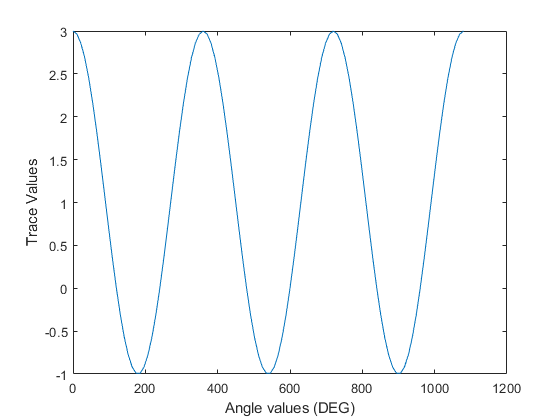

plot(theta*180/pi, TM); %Plot the results
ylabel("Trace Values");
xlabel("Angle values (DEG)");

               * Explanation here*

**The result is, as expected, a sinus function. This is expected due to that we know, based on the inverse mapping of a Rotation Matrix, that the angle only depends of the trace, and not the axis...**

## Exercise 3:

**Create** and **test** a function named **rotMat2Eaa** that given a rotation matrix returns its respective euler principal axis and angle.

Perform and show the results of the next verifications:

- Use the function on exercise 1 to create a rotation matrix from Euler axis information and ensure that the new function performs the inverse mapping correctly.

- What happens if you try to extract the angle and axis of the next matrices? What they have in common? 


$$\mathbf{R}_1 = \left( \begin{array}{ccc} 1 &0 &0\\ 0 &1&0 \\0 &0 & 1\end{array}\right),$$

$$\mathbf{R}_2 = \left( \begin{array}{ccc} -\frac{1}{3} &\frac{2}{3} &\frac{2}{3}\\ \frac{2}{3} &-\frac{1}{3}&\frac{2}{3} \\\frac{2}{3} &\frac{2}{3} & -\frac{1}{3}\end{array}\right),$$

$$\mathbf{R}_3 = \left( \begin{array}{ccc} 0 &0 &-1\\ 0 &-1&0 \\-1 &0 & 0\end{array}\right),$$


*            Comment here and include code if you need it.*

- Propose a solution for the past problem, **implement it** and verify that it works using the past matrices

*Solution here : *

## Exercise 4

**Find the rotation vectors** that rotates the cube to reach the next orientations:

- The green face points in the positive z direction and the orange face in the -y direction

-     $$r_1 = $$ ( , , )$$^T$$

- The orange face points in the -z direction and the blue face into the +y direction

-     $$r_2 = $$ ( , , )$$^T$$

- The red face points on the -x direction and the blue face into the -y direction

-     $$r_3 = $$ ( , , )$$^T$$

Use the function of the exercise 1 transform the orientation of the cube given by M for **every** of the previous cases and use the function  Cubeplot to  verify your previous answers

M = [    -1  -1 1;   %Node 1
    -1   1 1;   %Node 2
    1   1 1;   %Node 3
    1  -1 1;   %Node 4
    -1  -1 -1;  %Node 5
    -1   1 -1;  %Node 6
    1   1 -1;  %Node 7
    1  -1 -1]; %Node 8

R = Eaa2rotMat(90, [0,1,0]); %Orientation Case 1
R2 = Eaa2rotMat(90, [0,0,1]) * Eaa2rotMat(90, [1,0,0]) ; %Orientation Case 2
R3 = Eaa2rotMat(180, [1,0,0]) * Eaa2rotMat(180, [0,1,0]) ; %Orientation Case 3
M_mod = (R*M')';  %Case 1
M_mod2 =(R2*M')' % Case 2
M_mod3 =(R3*M')' % Case 3

Cubeplot(M_mod);  %Case 1
Cubeplot(M_mod2);  %Case 2
Cubeplot(M_mod3);  %Case 3

R =      0     0     1
     0     1     0
    -1     0     0


## Exercise 5

**Create** and **test **a function named **eAngles2rotM **that given a set of euler angles $(\varphi, \theta, \psi)$, return its respective rotation matrix.

- Calculate the determinant of the resulting rotation matrix 

R =      0    -1     0
     1     0     0
     0     0     1


R =      1     0     0
     0     0    -1
     0     1     0


- Compare the transpose and the inverse of the resulting matrix

R =      1     0     0
     0    -1     0
     0     0    -1


R =     -1     0     0
     0     1     0
     0     0    -1


**Create also** a function named **rotM2eAngles **that given a rotation matrix return its respective euler angles

- Ensure that the case for which theta = pi/2 + k*pi with k=1,2,.. is well implemented

- Use the first function of this exercise to create a rotation matrix from a set of euler angles and ensure that the new function performs the inverse mapping correctly.

M_mod2 =      1    -1    -1
     1    -1     1
     1     1     1
     1     1    -1
    -1    -1    -1
    -1    -1     1
    -1     1     1
    -1     1    -1


M_mod3 =      1     1     1
     1    -1     1
    -1    -1     1
    -1     1     1
     1     1    -1
     1    -1    -1
    -1    -1    -1
    -1     1    -1